clear;
% close all;
clc;

## Definitions

c: cycles per operation

global c p chip_frequency logScale printTimings USE_SUBPLOTS SAVE_PLOTS
c.memRead = 1;
c.mul = 1;
c.add = 1;
c.branch = 1;
c.memWrite = 1;
c.useTimings = 0;
c.dataTypeSize = 4;
chip_frequency = 100e6;
logScale = 0;
printTimings = 1;
USE_SUBPLOTS = false;
SAVE_PLOTS = true;
fprintf("Chip Frequency: %d MHz\n\n", chip_frequency / 1e6);

Chip Frequency: 100 MHz



## Network

p.conv1 = 1;
p.conv2 = 1;
p.conv3 = 1;
p.conv4 = 1;
p.conv5 = 1;
p.maxpool1 = 1;
p.maxpool2 = 1;
p.maxpool3 = 1;
p.linear1 = 1;
p.linear2 = 1;
p.linear3 = 1;


if USE_SUBPLOTS
	subplot(3,2,1);
else
	figure();
end
n1 = CreateNetwork();

Conv1: #Weights 23232 92928 0.04, #Outputs 193600 774400 77440.00
MaxPool1: #Weights 0 0 0.00, #Outputs 46656 186624 18662.40
Conv2: #Weights 307200 1228800 0.50, #Outputs 139968 559872 55987.20
MaxPool2: #Weights 0 0 0.00, #Outputs 32448 129792 12979.20
Conv3: #Weights 663552 2654208 1.09, #Outputs 64896 259584 25958.40
Conv4: #Weights 884736 3538944 1.45, #Outputs 43264 173056 17305.60
Conv5: #Weights 589824 2359296 0.97, #Outputs 43264 173056 17305.60
MaxPool3: #Weights 0 0 0.00, #Outputs 9216 36864 3686.40
Linear1: #Weights 37748736 150994944 61.79, #Outputs 4096 16384 1638.40
Linear2: #Weights 16777216 67108864 27.46, #Outputs 4096 16384 1638.40
Linear3: #Weights 4096000 16384000 6.70, #Outputs 1000 4000 400.00
Totals: #Weights 61090496 244361984 100.00, #Outputs 0 1000 100.00


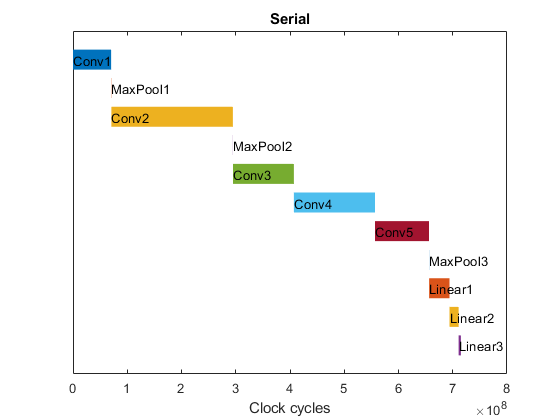

Serial: 7149.83 ms


n1 = ScheduleSerial(n1);
PrintSchedule(n1.arr, 'Serial');



if USE_SUBPLOTS
	subplot(3,2,2);
else
	figure();
end
n2 = CreateNetwork();

Conv1: #Weights 23232 92928 0.04, #Outputs 193600 774400 77440.00
MaxPool1: #Weights 0 0 0.00, #Outputs 46656 186624 18662.40
Conv2: #Weights 307200 1228800 0.50, #Outputs 139968 559872 55987.20
MaxPool2: #Weights 0 0 0.00, #Outputs 32448 129792 12979.20
Conv3: #Weights 663552 2654208 1.09, #Outputs 64896 259584 25958.40
Conv4: #Weights 884736 3538944 1.45, #Outputs 43264 173056 17305.60
Conv5: #Weights 589824 2359296 0.97, #Outputs 43264 173056 17305.60
MaxPool3: #Weights 0 0 0.00, #Outputs 9216 36864 3686.40
Linear1: #Weights 37748736 150994944 61.79, #Outputs 4096 16384 1638.40
Linear2: #Weights 16777216 67108864 27.46, #Outputs 4096 16384 1638.40
Linear3: #Weights 4096000 16384000 6.70, #Outputs 1000 4000 400.00
Totals: #Weights 61090496 244361984 100.00, #Outputs 0 1000 100.00


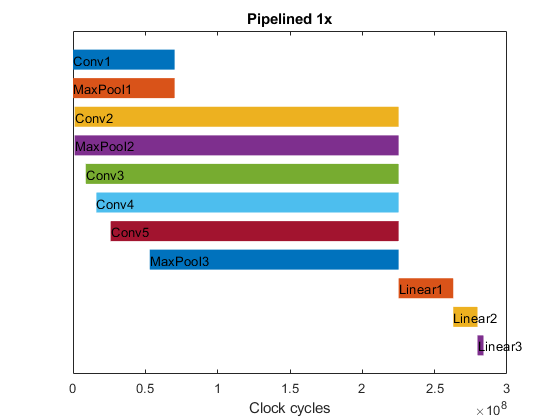

Pipelined 1x: 2837.17 ms


n2 = SchedulePipelined(n2);
PrintSchedule(n2.arr, 'Pipelined 1x');


p.conv1 = 11*11;
p.conv2 = 5*5;
p.conv3 = 3*3;
p.conv4 = 3*3;
p.conv5 = 3*3;
p.maxpool1 = 3*3;
p.maxpool2 = 3*3;
p.maxpool3 = 3*3;
p.linear1 = 1024;
p.linear2 = 1024;
p.linear3 = 1024;


if USE_SUBPLOTS
	subplot(3,2,3);
else
	figure();
end
n3 = CreateNetwork();

Conv1: #Weights 23232 92928 0.04, #Outputs 193600 774400 77440.00
MaxPool1: #Weights 0 0 0.00, #Outputs 46656 186624 18662.40
Conv2: #Weights 307200 1228800 0.50, #Outputs 139968 559872 55987.20
MaxPool2: #Weights 0 0 0.00, #Outputs 32448 129792 12979.20
Conv3: #Weights 663552 2654208 1.09, #Outputs 64896 259584 25958.40
Conv4: #Weights 884736 3538944 1.45, #Outputs 43264 173056 17305.60
Conv5: #Weights 589824 2359296 0.97, #Outputs 43264 173056 17305.60
MaxPool3: #Weights 0 0 0.00, #Outputs 9216 36864 3686.40
Linear1: #Weights 37748736 150994944 61.79, #Outputs 4096 16384 1638.40
Linear2: #Weights 16777216 67108864 27.46, #Outputs 4096 16384 1638.40
Linear3: #Weights 4096000 16384000 6.70, #Outputs 1000 4000 400.00
Totals: #Weights 61090496 244361984 100.00, #Outputs 0 1000 100.00


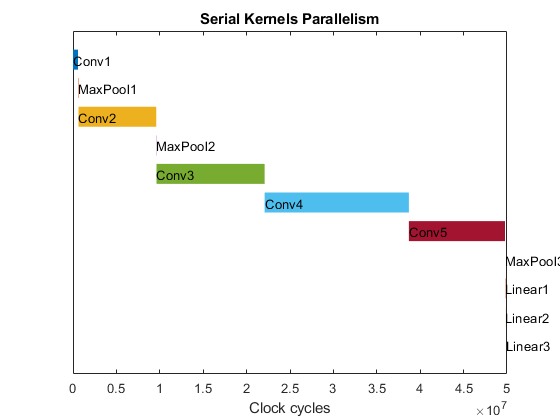

Serial Kernels Parallelism: 498.33 ms


n3 = ScheduleSerial(n3);
PrintSchedule(n3.arr, 'Serial Kernels Parallelism');


if USE_SUBPLOTS
	subplot(3,2,4);
else
	figure();
end
n4 = CreateNetwork();

Conv1: #Weights 23232 92928 0.04, #Outputs 193600 774400 77440.00
MaxPool1: #Weights 0 0 0.00, #Outputs 46656 186624 18662.40
Conv2: #Weights 307200 1228800 0.50, #Outputs 139968 559872 55987.20
MaxPool2: #Weights 0 0 0.00, #Outputs 32448 129792 12979.20
Conv3: #Weights 663552 2654208 1.09, #Outputs 64896 259584 25958.40
Conv4: #Weights 884736 3538944 1.45, #Outputs 43264 173056 17305.60
Conv5: #Weights 589824 2359296 0.97, #Outputs 43264 173056 17305.60
MaxPool3: #Weights 0 0 0.00, #Outputs 9216 36864 3686.40
Linear1: #Weights 37748736 150994944 61.79, #Outputs 4096 16384 1638.40
Linear2: #Weights 16777216 67108864 27.46, #Outputs 4096 16384 1638.40
Linear3: #Weights 4096000 16384000 6.70, #Outputs 1000 4000 400.00
Totals: #Weights 61090496 244361984 100.00, #Outputs 0 1000 100.00


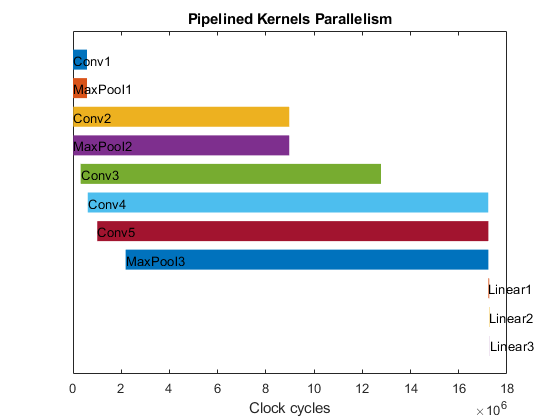

Pipelined Kernels Parallelism: 172.82 ms


n4 = SchedulePipelined(n4);
PrintSchedule(n4.arr, 'Pipelined Kernels Parallelism');


p.conv1 = 11*11*3;
p.conv2 = 5*5*64;
p.conv3 = 3*3*192;
p.conv4 = 3*3*384;
p.conv5 = 3*3*256;
p.maxpool1 = 3*3;
p.maxpool2 = 3*3;
p.maxpool3 = 3*3;
p.linear1 = 1024;
p.linear2 = 1024;
p.linear3 = 1024;


if USE_SUBPLOTS
	subplot(3,2,5);
else
	figure();
end
n5 = CreateNetwork();

Conv1: #Weights 23232 92928 0.04, #Outputs 193600 774400 77440.00
MaxPool1: #Weights 0 0 0.00, #Outputs 46656 186624 18662.40
Conv2: #Weights 307200 1228800 0.50, #Outputs 139968 559872 55987.20
MaxPool2: #Weights 0 0 0.00, #Outputs 32448 129792 12979.20
Conv3: #Weights 663552 2654208 1.09, #Outputs 64896 259584 25958.40
Conv4: #Weights 884736 3538944 1.45, #Outputs 43264 173056 17305.60
Conv5: #Weights 589824 2359296 0.97, #Outputs 43264 173056 17305.60
MaxPool3: #Weights 0 0 0.00, #Outputs 9216 36864 3686.40
Linear1: #Weights 37748736 150994944 61.79, #Outputs 4096 16384 1638.40
Linear2: #Weights 16777216 67108864 27.46, #Outputs 4096 16384 1638.40
Linear3: #Weights 4096000 16384000 6.70, #Outputs 1000 4000 400.00
Totals: #Weights 61090496 244361984 100.00, #Outputs 0 1000 100.00


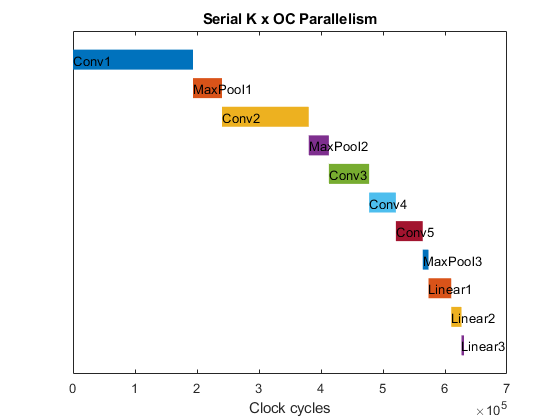

Serial K x OC Parallelism: 6.31 ms


n5 = ScheduleSerial(n5);
PrintSchedule(n5.arr, 'Serial K x OC Parallelism');


if USE_SUBPLOTS
	subplot(3,2,6);
else
	figure();
end
n6 = CreateNetwork();

Conv1: #Weights 23232 92928 0.04, #Outputs 193600 774400 77440.00
MaxPool1: #Weights 0 0 0.00, #Outputs 46656 186624 18662.40
Conv2: #Weights 307200 1228800 0.50, #Outputs 139968 559872 55987.20
MaxPool2: #Weights 0 0 0.00, #Outputs 32448 129792 12979.20
Conv3: #Weights 663552 2654208 1.09, #Outputs 64896 259584 25958.40
Conv4: #Weights 884736 3538944 1.45, #Outputs 43264 173056 17305.60
Conv5: #Weights 589824 2359296 0.97, #Outputs 43264 173056 17305.60
MaxPool3: #Weights 0 0 0.00, #Outputs 9216 36864 3686.40
Linear1: #Weights 37748736 150994944 61.79, #Outputs 4096 16384 1638.40
Linear2: #Weights 16777216 67108864 27.46, #Outputs 4096 16384 1638.40
Linear3: #Weights 4096000 16384000 6.70, #Outputs 1000 4000 400.00
Totals: #Weights 61090496 244361984 100.00, #Outputs 0 1000 100.00


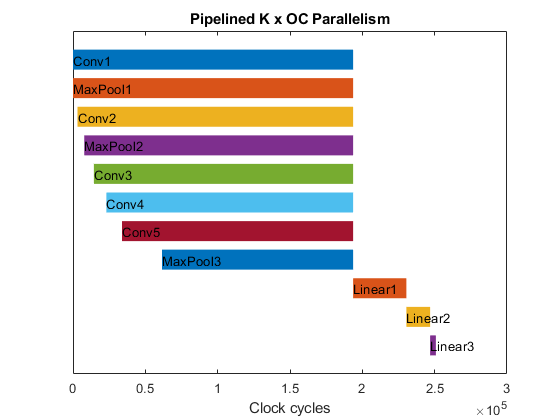

Pipelined K x OC Parallelism: 2.51 ms


n6 = SchedulePipelined(n6);
PrintSchedule(n6.arr, 'Pipelined K x OC Parallelism');


if USE_SUBPLOTS && SAVE_PLOTS
	saveas('output/withSubplots/Scheduling.png');
end